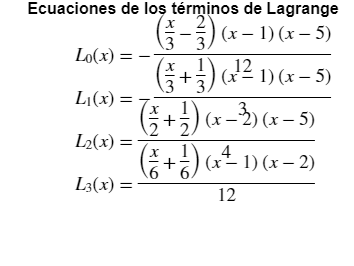

function P = lagrange_interpolation(X, Y)
    % Calcula el polinomio de interpolación de Lagrange basado en los puntos (X, Y).

    syms x;  % Crear un símbolo para la variable x
    n = length(X);  % Número de puntos
    
    % Inicializar el polinomio a 0
    P = 0;
    
    % Crear una figura para mostrar las ecuaciones simbólicas
    figure;
    
    % Iterar sobre todos los puntos para calcular el polinomio de Lagrange
    for k = 1:n
        % Inicializar L_k como 1 (L_k representa el k-ésimo término del polinomio de Lagrange)
        L_k = 1;
        
        % Calcular el término L_k usando la productoria
        for i = 1:n
            if i ~= k  % Excluir el índice k de la productoria
                L_k = L_k * (x - X(i)) / (X(k) - X(i));
            end
        end
        
        % Simplificar L_k(x)
        L_k_simplified = simplify(L_k);
        
        % Convertir la expresión simbólica a formato LaTeX
        L_k_latex = latex(L_k_simplified);
        
        % Mostrar la ecuación simbólica en una figura gráfica
        text(0.1, 1.1 - k*0.2, ['$L_' num2str(k-1) '(x) = ' L_k_latex '$'], ...
             'Interpreter', 'latex', 'FontSize', 14);
        
        % Sumar el término correspondiente al polinomio total
        P = P + Y(k) * L_k;
    end
    
    axis off;  % Apagar los ejes para que solo se vea el texto
    title('Ecuaciones de los términos de Lagrange', 'FontSize', 12);
end

% Paso 1: Pedir los valores de los puntos al usuario
n = input('Número de puntos: ');  % Solicitar el número de puntos

% Inicializar los vectores de X y Y
X = zeros(n, 1);
Y = zeros(n, 1);

% Solicitar los valores de X y Y
for i = 1:n
    X(i) = input(['X(' num2str(i) '): ']);  % Solicitar el valor de X(i)
    Y(i) = input(['Y(' num2str(i) '): ']);  % Solicitar el valor de Y(i)
end

% Paso 2: Calcular el polinomio de interpolación de Lagrange y mostrar las ecuaciones
P = lagrange_interpolation(X, Y);


% Paso 3: Simplificar el polinomio resultante
disp('Polinomio de Interpolación de Lagrange (P(x)):');

Polinomio de Interpolación de Lagrange (P(x)):


P_simplified = simplify(P);
disp(P_simplified);

$$-\frac{35\,x^{3}}{72}+\frac{113\,x^{2}}{36}-\frac{145\,x}{72}-\frac{59}{36}$$


% Paso 4: Evaluar el polinomio en los puntos originales para verificar la interpolación
syms x;
Y_interp = double(subs(P_simplified, x, X));
disp('Valores interpolados:');

Valores interpolados:


disp(Y_interp);

     4
     3
    -1
     6



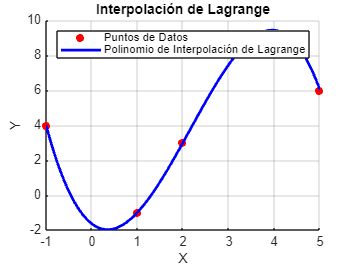


% ---------- GRAFICAR RESULTADOS ----------

% Crear una figura para graficar los resultados
figure;

% Graficar los puntos originales
scatter(X, Y, 'ro', 'filled', 'DisplayName', 'Puntos de Datos');
hold on;

% Crear un rango de valores para graficar el polinomio de interpolación
X_plot = linspace(min(X), max(X), 100)';
Y_plot = double(subs(P_simplified, x, X_plot));

% Graficar el polinomio de interpolación
plot(X_plot, Y_plot, 'b-', 'LineWidth', 2, 'DisplayName', 'Polinomio de Interpolación de Lagrange');
xlabel('X');
ylabel('Y');
title('Interpolación de Lagrange');
legend('show');
grid on;